# Example for using the `scale_data` function.

Copyright © 2022 Tamas Kis

Create a data set $\mathbf{y}$ vs. $\mathbf{x}$ where $\mathbf{x}$ stores $x$-values between (and including) 0 and 10, separated by 0.5, and where the $i^{\textrm{th}}$ $y$-value is given by $y_i =x_i^2 -5$.

x = 0:0.5:10;
y = x.^2-5;

Scale this data set so that its first point will be at $\left(-2,-2\right)$, and its end point will be at $\left(12,90\right)$.

[x_new,y_new] = scale_data(x,y,[-2,-2],[12,90]);

Plot the original and scaled data on the same figure.

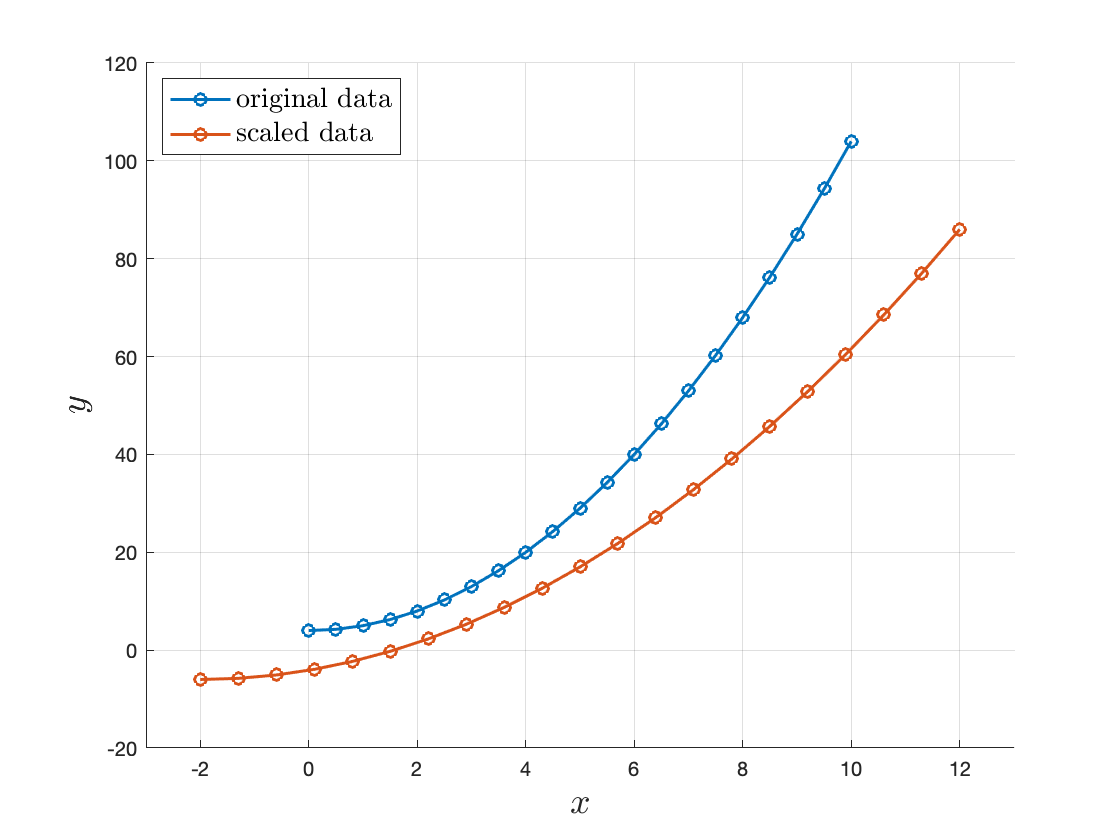

figure;
hold on;
plot(x,y,'-o','LineWidth',1.5);
plot(x_new,y_new,'-o','LineWidth',1.5);
grid on;
xlim([-3,13]);
ylim([-20,120]);
hold off;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('original data','scaled data','Interpreter','latex','FontSize',14,...
    'Location','northwest');